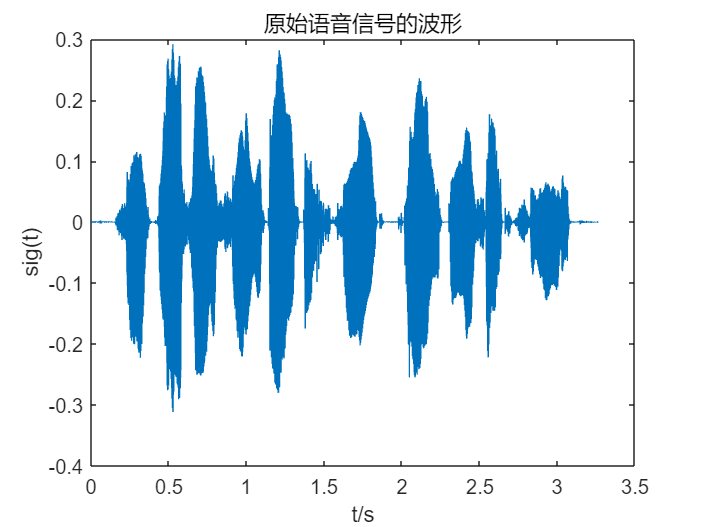

clear, close all
%Task1
% 导入语音信号
[sig1, fs] = audioread("C_01_01(2).wav");
s1=fftshift(fft(sig1',length(sig1)));
% 得到音频播放时间
Nsig = length(sig1);
t = (0:Nsig-1)./fs;
w=linspace(-fs/2,fs/2,length(sig1));
% 播放原始音频信号
%sound(sig1, fs);

% 显示信号波形
figure;
plot(t, sig1'), title('原始语音信号的波形'), xlabel('t/s'), ylabel('sig(t)')

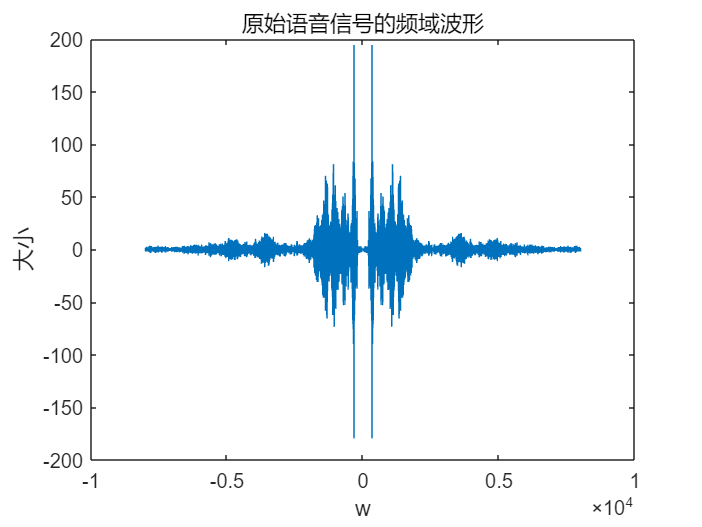

plot(w,s1),title('原始语音信号的频域波形'), xlabel('w'), ylabel("大小")

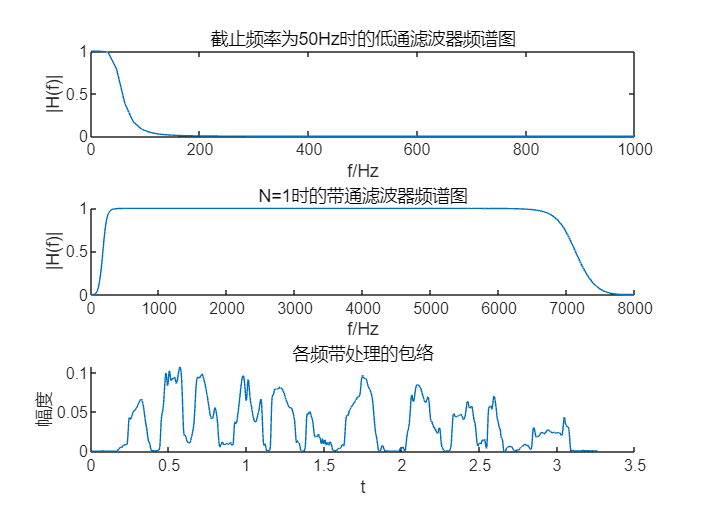



fc = 50;
N1 = 1; N2 = 2; N3 = 4; N4 = 6; N5 = 8; N6 = 16;

sig1_1_50 = tone_vocoder(sig1, N1, fc, fs);

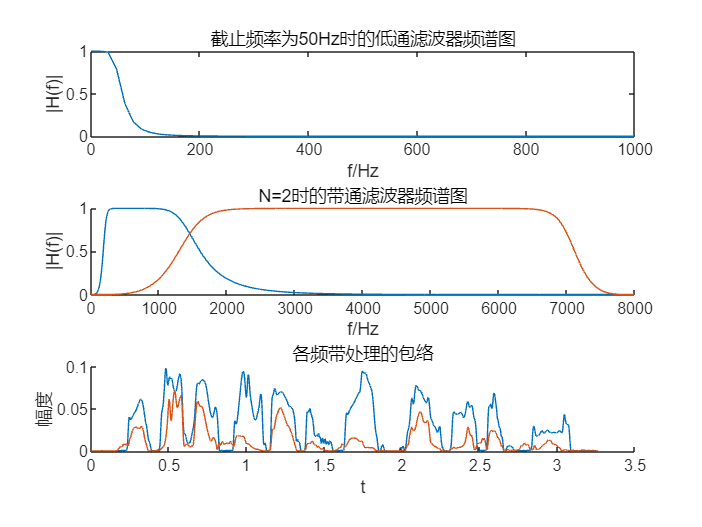

% sound(sig1_1_50, fs)
filename = "sig1_1_50.wav";
audiowrite(filename, sig1_1_50, fs);

sig1_2_50 = tone_vocoder(sig1, N2, fc, fs);

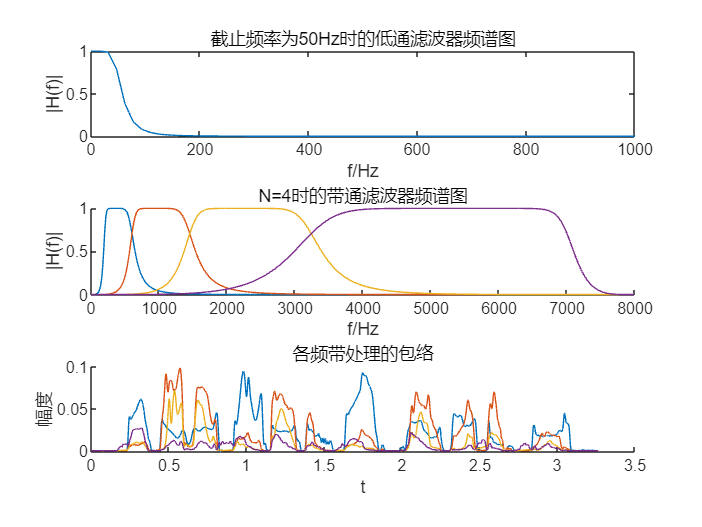

% sound(sig1_2_50, fs)
filename = "sig1_2_50.wav";
audiowrite(filename, sig1_2_50, fs);

sig1_4_50 = tone_vocoder(sig1, N3, fc, fs);

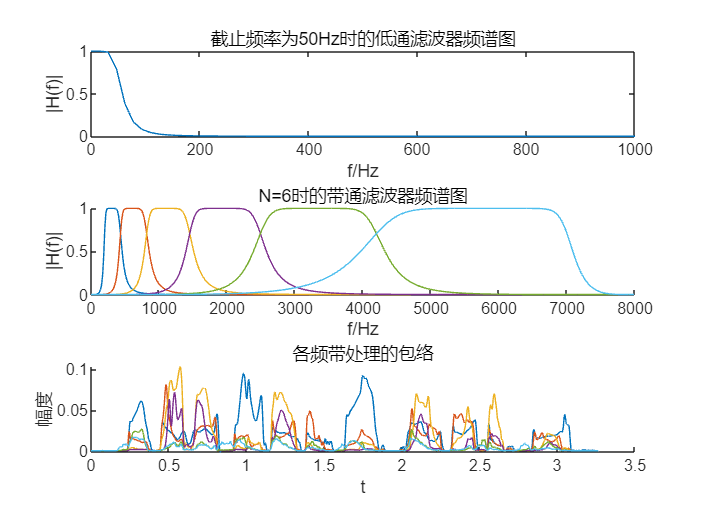

% sound(sig1_4_50, fs)
filename = "sig1_4_50.wav";
audiowrite(filename, sig1_4_50, fs);

sig1_6_50 = tone_vocoder(sig1, N4, fc, fs);

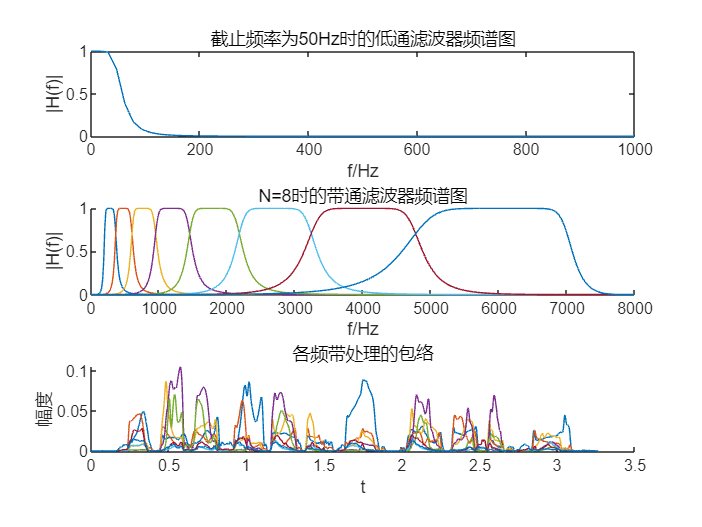

% sound(sig1_6_50, fs)
filename = "sig1_6_50.wav";
audiowrite(filename, sig1_6_50, fs);

sig1_8_50 = tone_vocoder(sig1, N5, fc, fs);

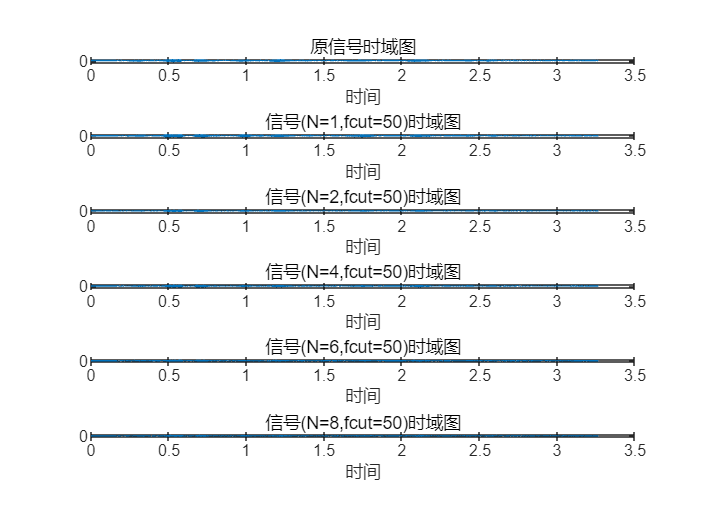

% sound(sig1_8_50, fs)
filename = "sig1_8_50.wav";
audiowrite(filename, sig1_8_50, fs);


w_sig1_1_50=fftshift(fft(sig1_1_50,length(sig1_1_50)));
w_sig1_2_50=fftshift(fft(sig1_2_50,length(sig1_2_50)));
w_sig1_4_50=fftshift(fft(sig1_4_50,length(sig1_4_50)));
w_sig1_6_50=fftshift(fft(sig1_6_50,length(sig1_6_50)));
w_sig1_8_50=fftshift(fft(sig1_8_50,length(sig1_8_50)));

figure
subplot(6,1,1),plot(t,sig1'),xlabel("时间"),ylabel("振幅"),title("原信号时域图")
subplot(6,1,2),plot(t,sig1_1_50),xlabel("时间"),ylabel("振幅"),title("信号(N=1,fcut=50)时域图")
subplot(6,1,3),plot(t,sig1_2_50),xlabel("时间"),ylabel("振幅"),title("信号(N=2,fcut=50)时域图")
subplot(6,1,4),plot(t,sig1_4_50),xlabel("时间"),ylabel("振幅"),title("信号(N=4,fcut=50)时域图")
subplot(6,1,5),plot(t,sig1_6_50),xlabel("时间"),ylabel("振幅"),title("信号(N=6,fcut=50)时域图")
subplot(6,1,6),plot(t,sig1_8_50),xlabel("时间"),ylabel("振幅"),title("信号(N=8,fcut=50)时域图")



figure
subplot(6,1,1),plot(w,s1),xlabel("频率"),ylabel("大小"),title("原信号频域图")

subplot(6,1,2),plot(w,w_sig1_1_50),xlabel("频率"),ylabel("大小"),title("信号(N=1,fcut=50)频域图")

subplot(6,1,3),plot(w,w_sig1_2_50),xlabel("频率"),ylabel("大小"),title("信号(N=2,fcut=50)频域图")

subplot(6,1,4),plot(w,w_sig1_4_50),xlabel("频率"),ylabel("大小"),title("信号(N=4,fcut=50)频域图")

subplot(6,1,5),plot(w,w_sig1_6_50),xlabel("频率"),ylabel("大小"),title("信号(N=6,fcut=50)频域图")

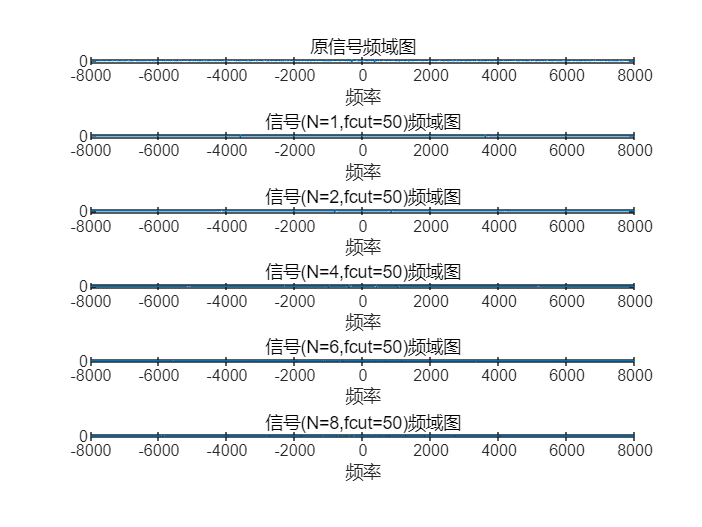

subplot(6,1,6),plot(w,w_sig1_8_50),xlabel("频率"),ylabel("大小"),title("信号(N=8,fcut=50)频域图")

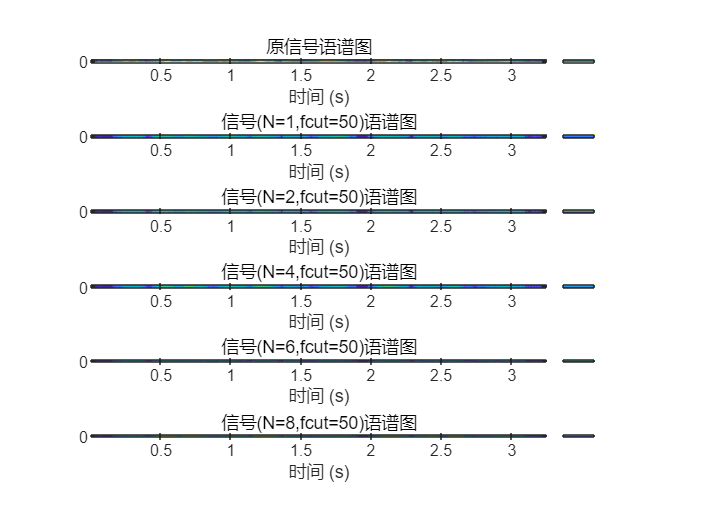


figure
subplot(6,1,1),spectrogram(sig1,256,128,256,16000,'yaxis'),title("原信号语谱图")
subplot(6,1,2),spectrogram(sig1_1_50,256,128,256,16000,'yaxis'),title("信号(N=1,fcut=50)语谱图")
subplot(6,1,3),spectrogram(sig1_2_50,256,128,256,16000,'yaxis'),title("信号(N=2,fcut=50)语谱图")
subplot(6,1,4),spectrogram(sig1_4_50,256,128,256,16000,'yaxis'),title("信号(N=4,fcut=50)语谱图")
subplot(6,1,5),spectrogram(sig1_6_50,256,128,256,16000,'yaxis'),title("信号(N=6,fcut=50)语谱图")
subplot(6,1,6),spectrogram(sig1_8_50,256,128,256,16000,'yaxis'),title("信号(N=8,fcut=50)语谱图")

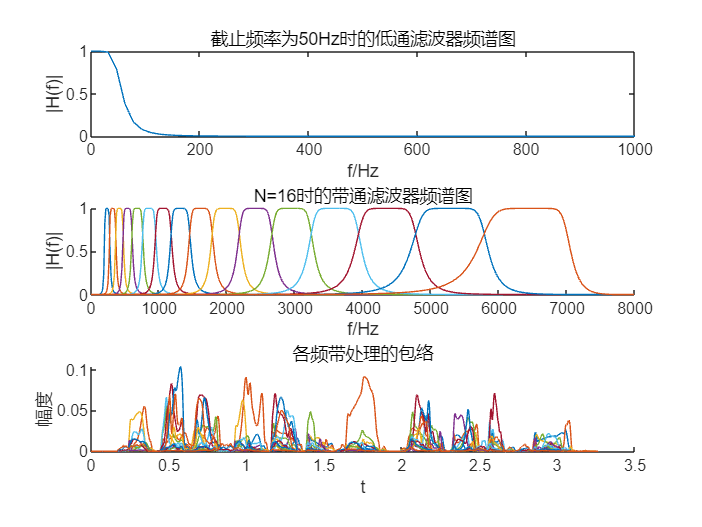


sig1_16_50=tone_vocoder(sig1,16,fc,fs);

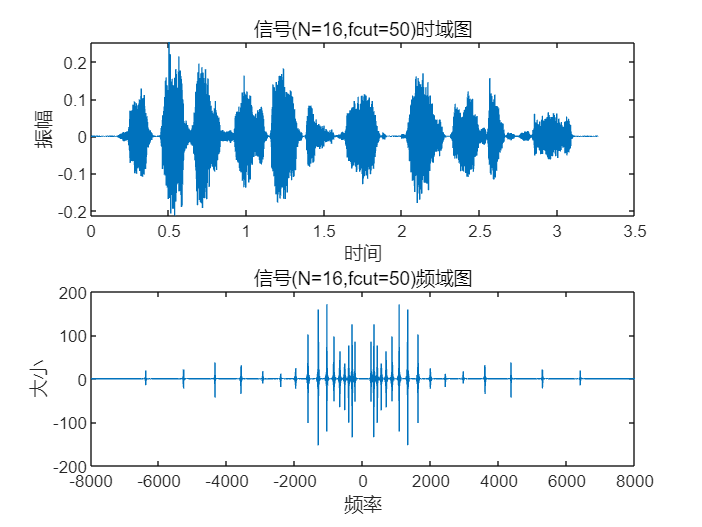

w_sig1_16_50=fftshift(fft(sig1_16_50,length(sig1_16_50)));
figure
subplot(2,1,1),plot(t,sig1_16_50),xlabel("时间"),ylabel("振幅"),title("信号(N=16,fcut=50)时域图")
subplot(2,1,2),plot(w,w_sig1_16_50),xlabel("频率"),ylabel("大小"),title("信号(N=16,fcut=50)频域图")

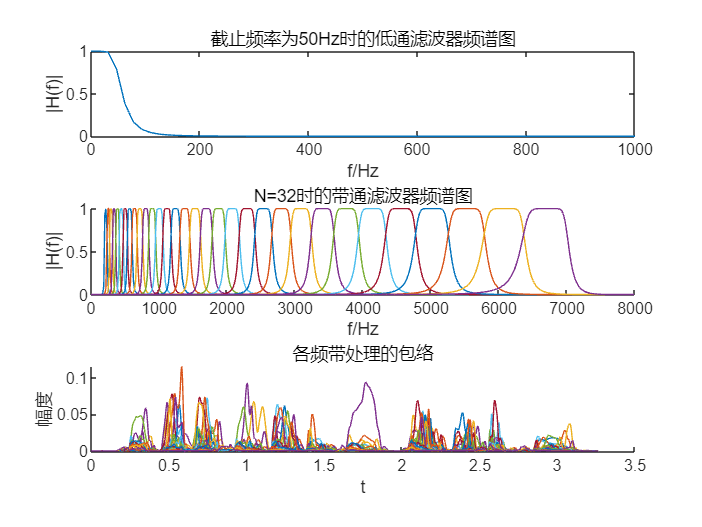




sig1_32_50=tone_vocoder(sig1,32,fc,fs);

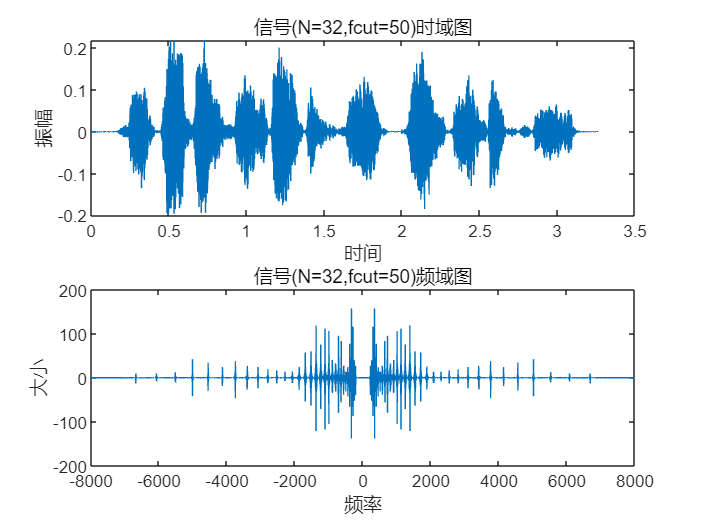

w_sig1_32_50=fftshift(fft(sig1_32_50,length(sig1_32_50)));
figure
subplot(2,1,1),plot(t,sig1_32_50),xlabel("时间"),ylabel("振幅"),title("信号(N=32,fcut=50)时域图")
subplot(2,1,2),plot(w,w_sig1_32_50),xlabel("频率"),ylabel("大小"),title("信号(N=32,fcut=50)频域图")


sig1_64_50=tone_vocoder(sig1,16,fc,fs);

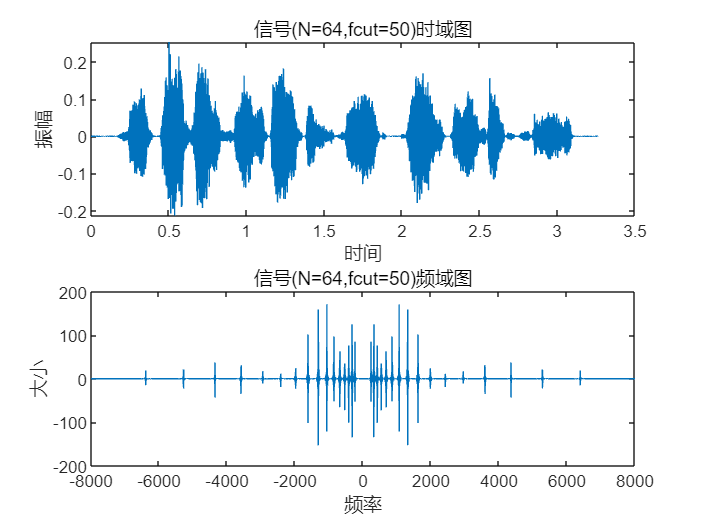

w_sig1_64_50=fftshift(fft(sig1_64_50,length(sig1_64_50)));
figure
subplot(2,1,1),plot(t,sig1_64_50),xlabel("时间"),ylabel("振幅"),title("信号(N=64,fcut=50)时域图")
subplot(2,1,2),plot(w,w_sig1_64_50),xlabel("频率"),ylabel("大小"),title("信号(N=64,fcut=50)频域图")


sig1_128_50=tone_vocoder(sig1,16,fc,fs);

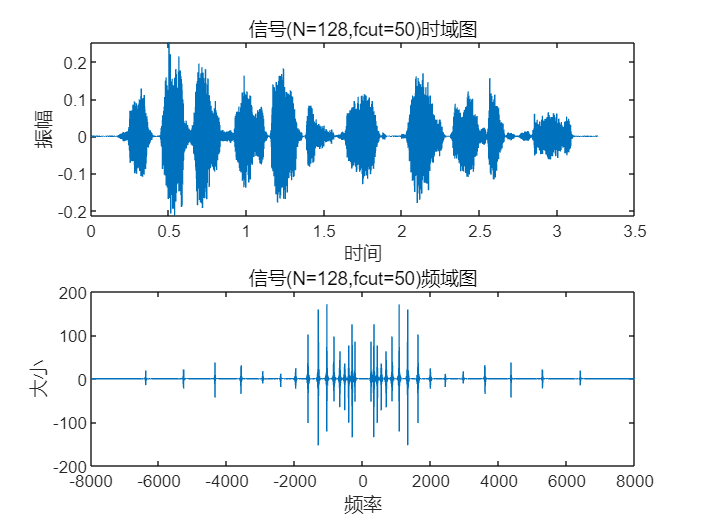

w_sig1_128_50=fftshift(fft(sig1_128_50,length(sig1_128_50)));
figure
subplot(2,1,1),plot(t,sig1_128_50),xlabel("时间"),ylabel("振幅"),title("信号(N=128,fcut=50)时域图")
subplot(2,1,2),plot(w,w_sig1_128_50),xlabel("频率"),ylabel("大小"),title("信号(N=128,fcut=50)频域图")

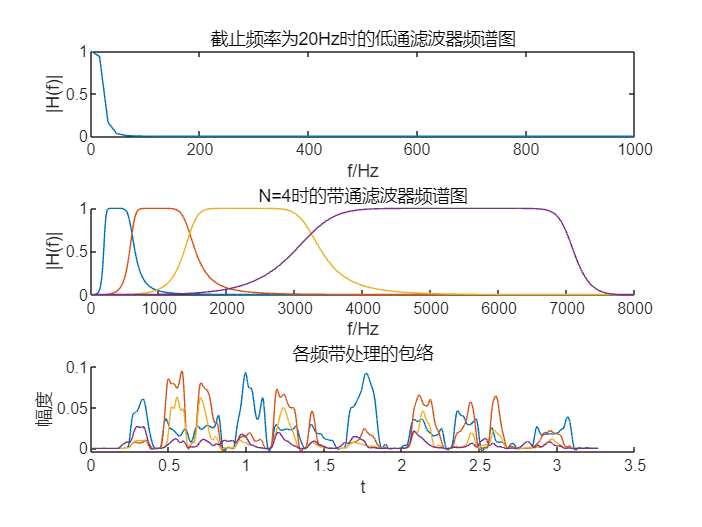

%Task2
[s,fs]=audioread("C_01_01(2).wav");
N=4;

t=1/fs:1/fs:length(s)*1/fs;
w=linspace(-fs/2,fs/2,length(s));
s1=fftshift(fft(s',length(s)));


sig1_4_20=tone_vocoder(s,N,20,fs);

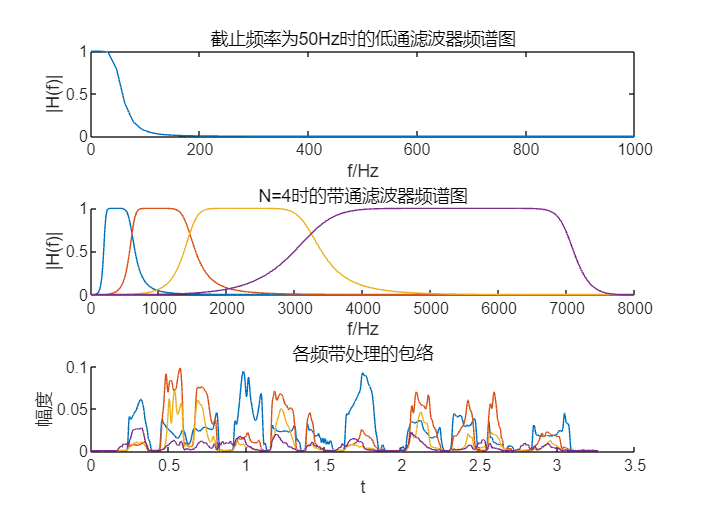

sig1_4_50=tone_vocoder(s,N,50,fs);

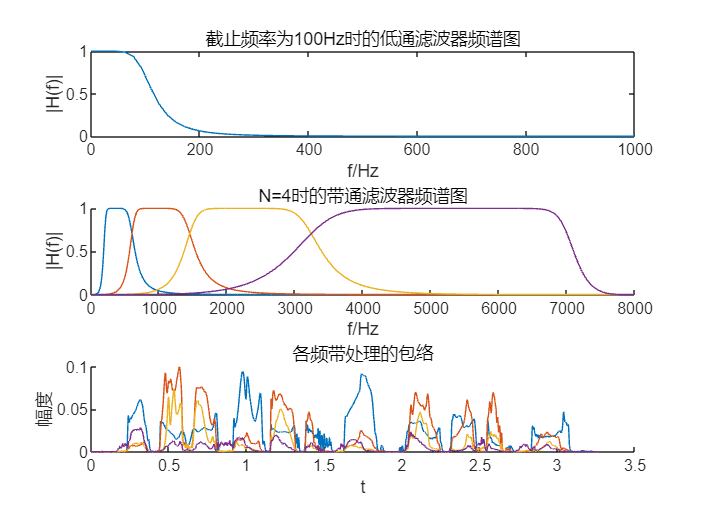

sig1_4_100=tone_vocoder(s,N,100,fs);

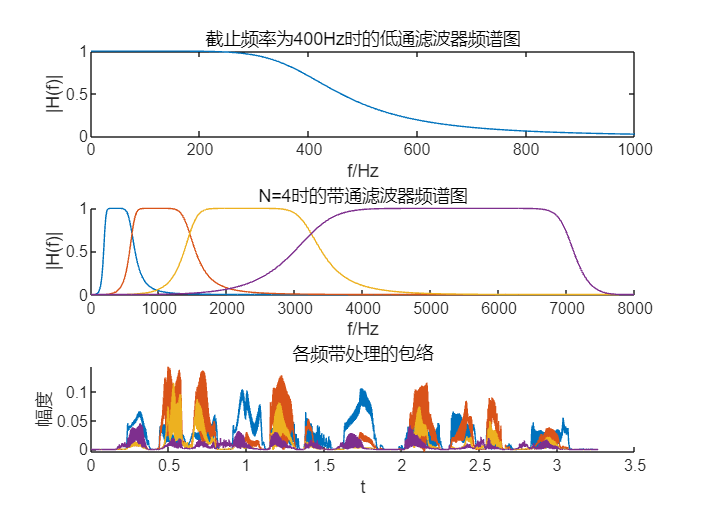

sig1_4_400=tone_vocoder(s,N,400,fs);

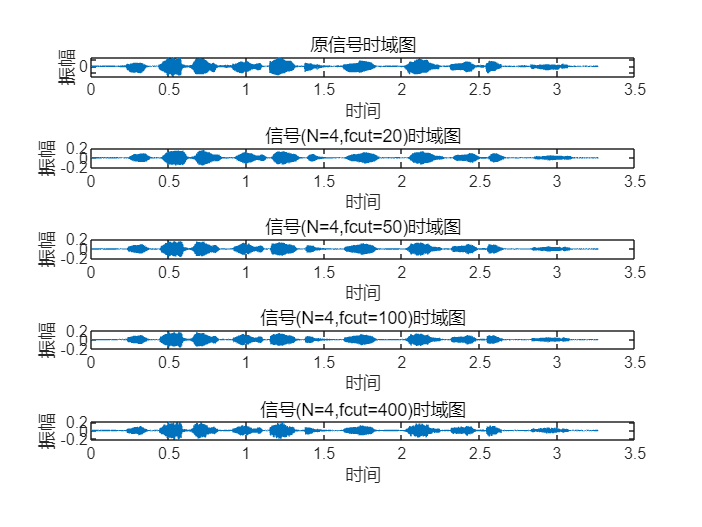


w_sig1_4_20=fftshift(fft(sig1_4_20,length(sig1_4_20)));
w_sig1_4_50=fftshift(fft(sig1_4_50,length(sig1_4_50)));
w_sig1_4_100=fftshift(fft(sig1_4_100,length(sig1_4_100)));
w_sig1_4_400=fftshift(fft(sig1_4_400,length(sig1_4_400)));

figure
subplot(5,1,1),plot(t,s'),xlabel("时间"),ylabel("振幅"),title("原信号时域图")
subplot(5,1,2),plot(t,sig1_4_20),xlabel("时间"),ylabel("振幅"),title("信号(N=4,fcut=20)时域图")
subplot(5,1,3),plot(t,sig1_4_50),xlabel("时间"),ylabel("振幅"),title("信号(N=4,fcut=50)时域图")
subplot(5,1,4),plot(t,sig1_4_100),xlabel("时间"),ylabel("振幅"),title("信号(N=4,fcut=100)时域图")
subplot(5,1,5),plot(t,sig1_4_400),xlabel("时间"),ylabel("振幅"),title("信号(N=4,fcut=400)时域图")


figure
subplot(5,1,1),plot(w,s1),xlabel("频率"),ylabel("大小"),title("原信号频域图")

subplot(5,1,2),plot(w,w_sig1_4_20),xlabel("频率"),ylabel("大小"),title("信号(N=4,fcut=20)频域图")

subplot(5,1,3),plot(w,w_sig1_4_50),xlabel("频率"),ylabel("大小"),title("信号(N=4,fcut=50)频域图")

subplot(5,1,4),plot(w,w_sig1_4_100),xlabel("频率"),ylabel("大小"),title("信号(N=4,fcut=100)频域图")

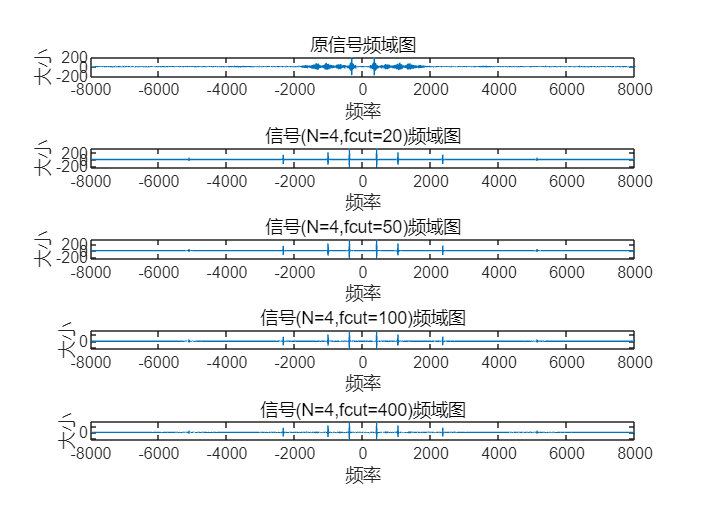

subplot(5,1,5),plot(w,w_sig1_4_400),xlabel("频率"),ylabel("大小"),title("信号(N=4,fcut=400)频域图")

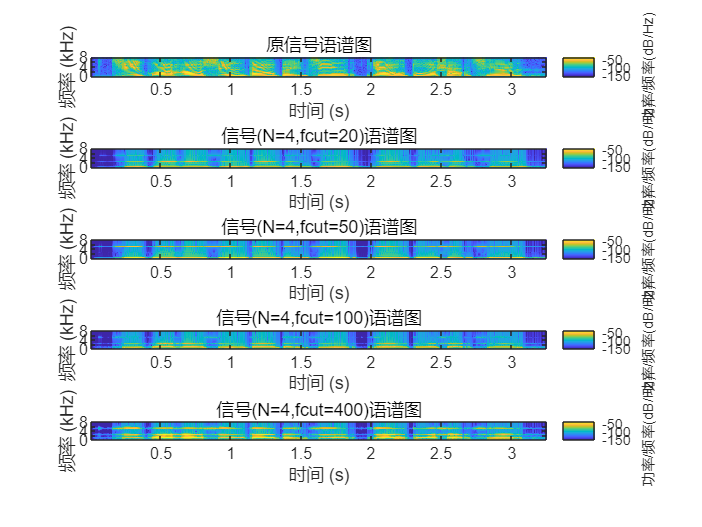


figure
subplot(5,1,1),spectrogram(s,256,128,256,16000,'yaxis'),title("原信号语谱图")
subplot(5,1,2),spectrogram(sig1_4_20,256,128,256,16000,'yaxis'),title("信号(N=4,fcut=20)语谱图")
subplot(5,1,3),spectrogram(sig1_4_50,256,128,256,16000,'yaxis'),title("信号(N=4,fcut=50)语谱图")
subplot(5,1,4),spectrogram(sig1_4_100,256,128,256,16000,'yaxis'),title("信号(N=4,fcut=100)语谱图")
subplot(5,1,5),spectrogram(sig1_4_400,256,128,256,16000,'yaxis'),title("信号(N=4,fcut=400)语谱图")

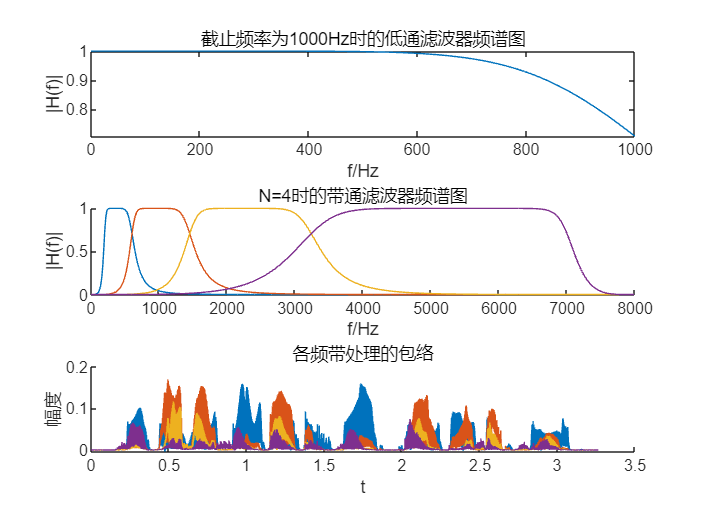



sig1_4_1000=tone_vocoder(s,N,1000,fs);

w_sig1_4_1000=fftshift(fft(sig1_4_1000,length(sig1_4_1000)));
figure
subplot(3,1,1),plot(t,sig1_4_1000),xlabel("时间"),ylabel("振幅"),title("信号(N=4,fcut=1000)时域图")
subplot(3,1,2),plot(w,w_sig1_4_1000),xlabel("频率"),ylabel("大小"),title("信号(N=4,fcut=1000)频域图")

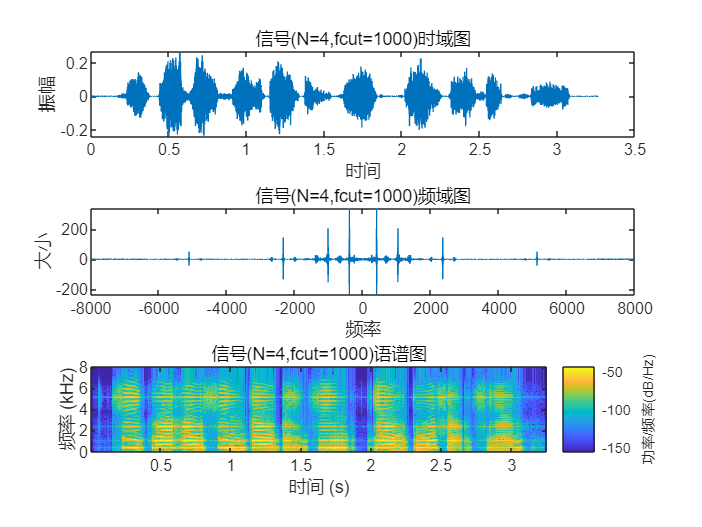

subplot(3,1,3),spectrogram(sig1_4_1000,256,128,256,16000,'yaxis'),title("信号(N=4,fcut=1000)语谱图")

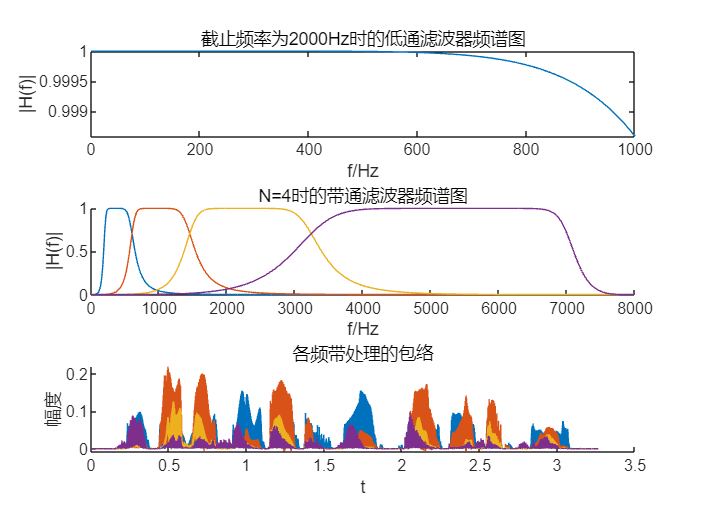



sig1_4_2000=tone_vocoder(s,N,2000,fs);

w_sig1_4_2000=fftshift(fft(sig1_4_2000,length(sig1_4_2000)));
figure
subplot(3,1,1),plot(t,sig1_4_2000),xlabel("时间"),ylabel("振幅"),title("信号(N=4,fcut=2000)时域图")
subplot(3,1,2),plot(w,w_sig1_4_2000),xlabel("频率"),ylabel("大小"),title("信号(N=4,fcut=2000)频域图")

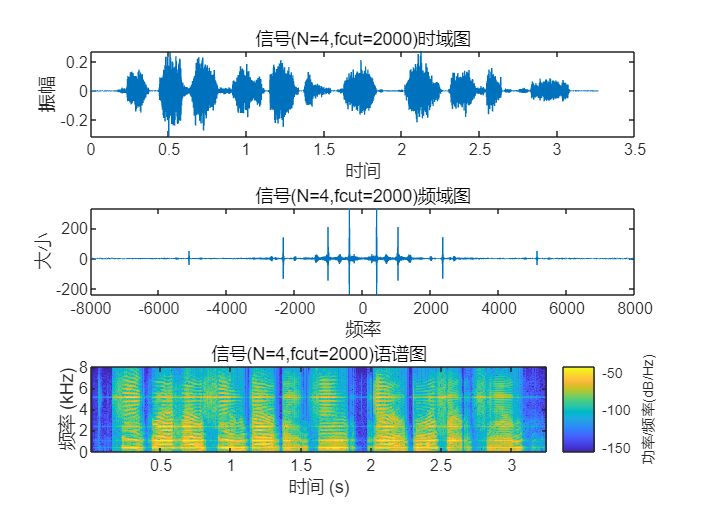

subplot(3,1,3),spectrogram(sig1_4_2000,256,128,256,16000,'yaxis'),title("信号(N=4,fcut=2000)语谱图")


%sound(sig1_4_2000,16000)


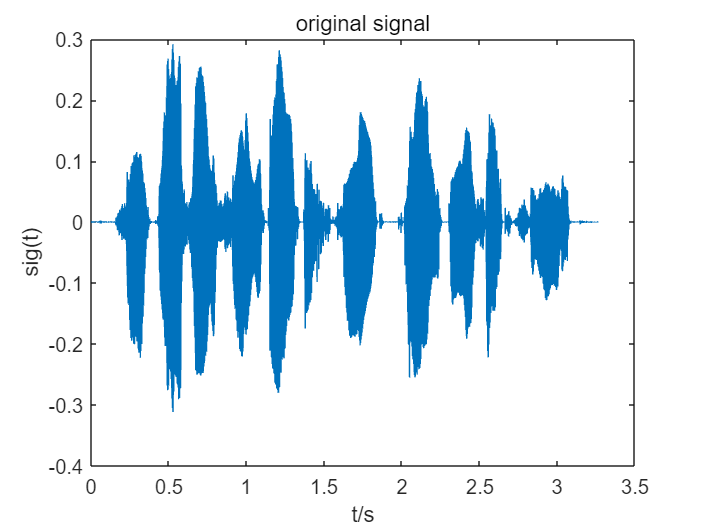

%Task3
[s,fs]=audioread("C_01_01(1).wav");
fcut = 50;
t=1/fs:1/fs:length(s)*1/fs;%obtain signal time 
figure;
plot(t,s),title('original signal'),xlabel('t/s'),ylabel('sig(t)');

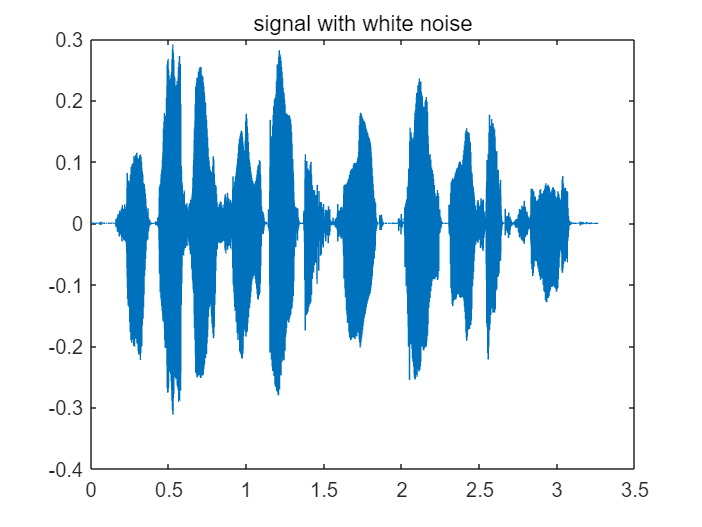

w=linspace(-fs/2,fs/2,length(s));
s1=fftshift(fft(s',length(s)));%obtain DTFT of signal
%N and cut-off frequency sequence
Nseq =[2,4,6,8,16,64];
fcutseq = [20,50,100,400];
X = zeros(6,4);
normS = norm(s);
SSN =  SSNgerator(s,fs);% SSNerator for obtain an signal having SNA to -5dB.
%s = (s+SSN')/norm(s+SSN')*norm(s);%Energy normalization
figure;
plot(t,s),title('signal with white noise');

%genearte signals with different N and same cut-off frequency. 
sig1_2_50=tone_vocoder(s,2,fcut,fs);

sig1_4_50=tone_vocoder(s,4,fcut,fs);

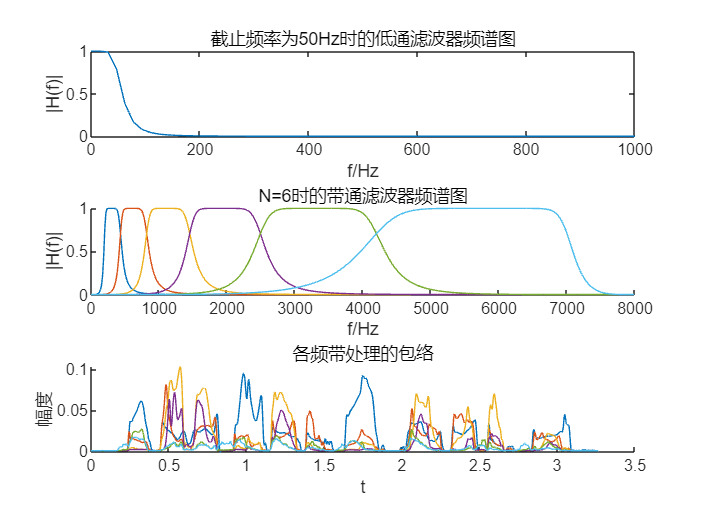

sig1_6_50=tone_vocoder(s,6,fcut,fs);

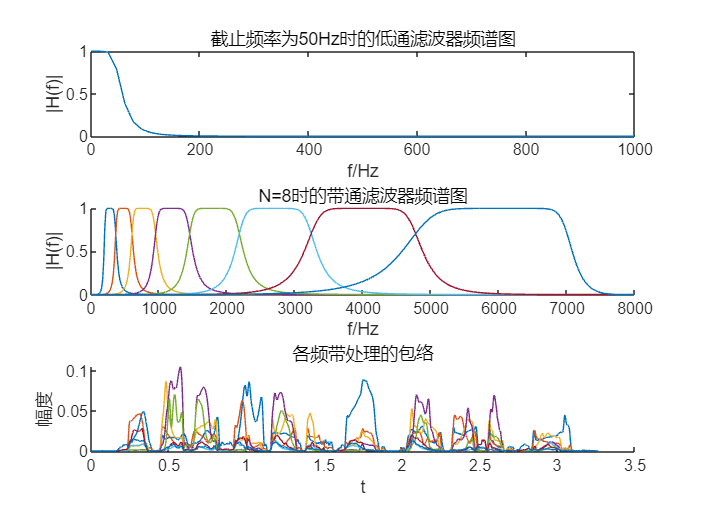

sig1_8_50=tone_vocoder(s,8,fcut,fs);

sig1_16_50=tone_vocoder(s,16,fcut,fs);

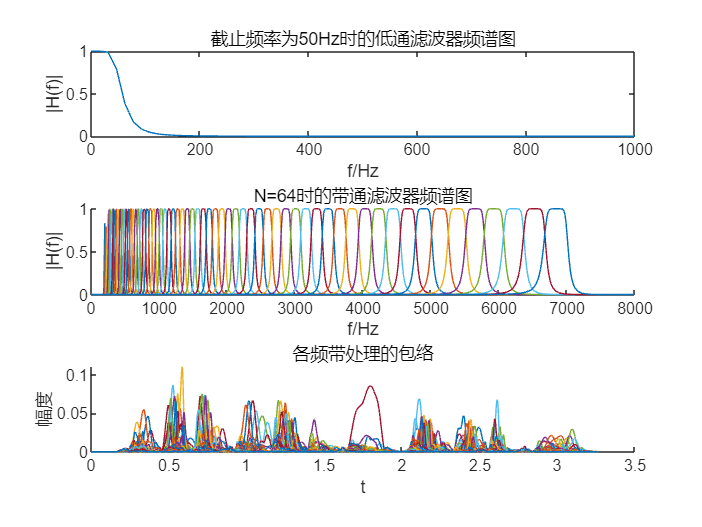

sig1_64_50=tone_vocoder(s,64,fcut,fs);

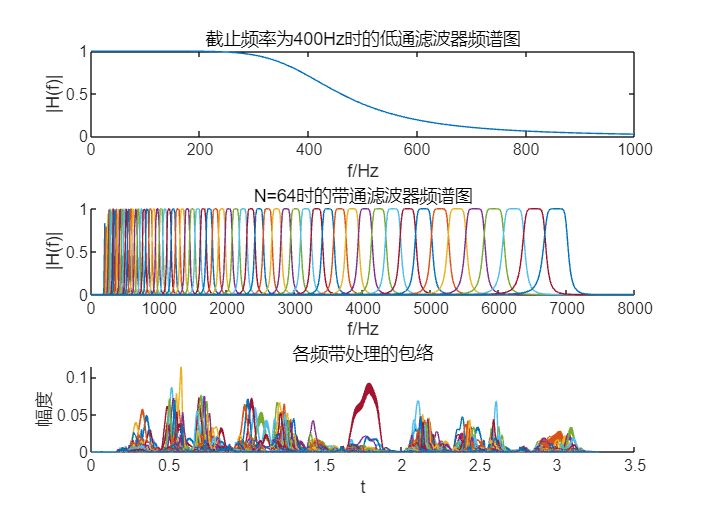

sig1_64_400=tone_vocoder(s,64,400,fs);

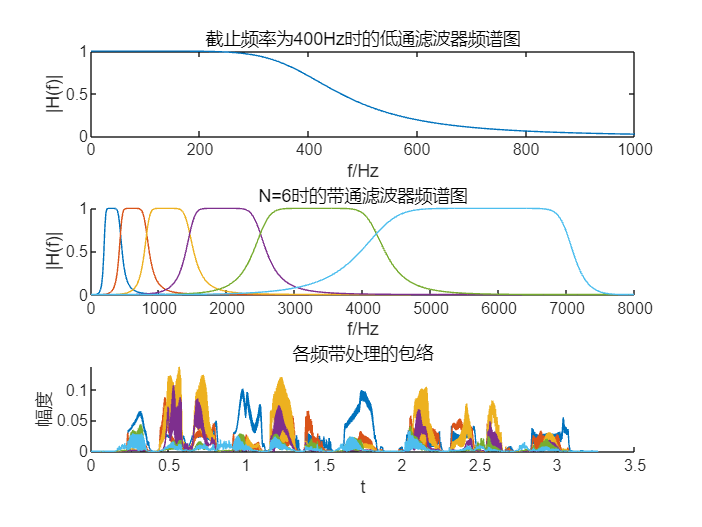

sig1_6_400 = tone_vocoder(s,6,400,fs);

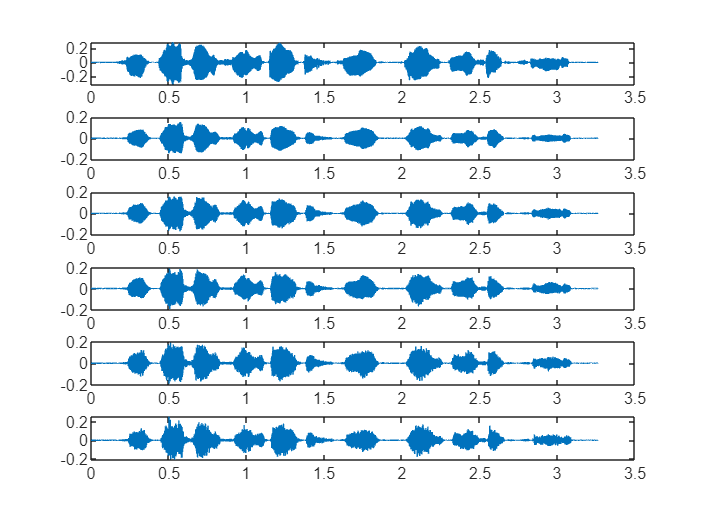


%frequency spectrum
w_sig1_2_50=fftshift(fft(sig1_2_50,length(sig1_2_50)));
w_sig1_4_50=fftshift(fft(sig1_4_50,length(sig1_4_50)));
w_sig1_6_50=fftshift(fft(sig1_6_50,length(sig1_6_50)));
w_sig1_8_50=fftshift(fft(sig1_8_50,length(sig1_8_50)));
w_sig1_16_50=fftshift(fft(sig1_16_50,length(sig1_16_50)));

figure
subplot(6,1,1),plot(t,s')
subplot(6,1,2),plot(t,sig1_2_50)
subplot(6,1,3),plot(t,sig1_4_50)
subplot(6,1,4),plot(t,sig1_6_50)
subplot(6,1,5),plot(t,sig1_8_50)
subplot(6,1,6),plot(t,sig1_16_50)

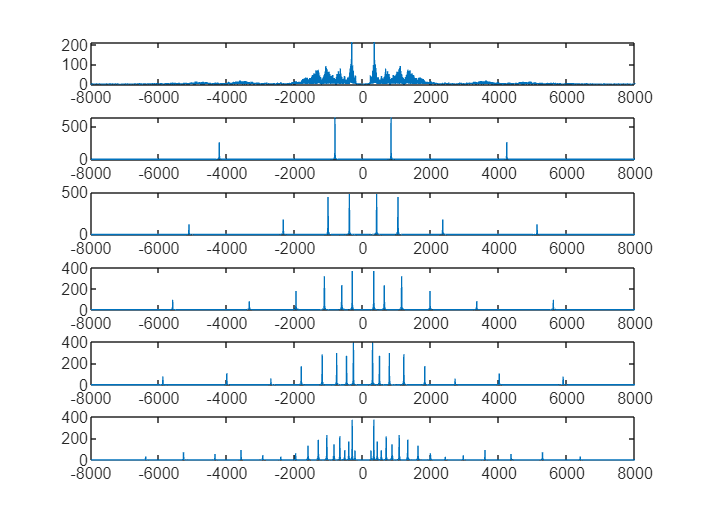


figure
subplot(6,1,1),plot(w,abs((s1)))
subplot(6,1,2),plot(w,abs((w_sig1_2_50)))
subplot(6,1,3),plot(w,abs((w_sig1_4_50)))
subplot(6,1,4),plot(w,abs((w_sig1_6_50)))
subplot(6,1,5),plot(w,abs((w_sig1_8_50)))
subplot(6,1,6),plot(w,abs((w_sig1_16_50)))


SNAcheck = (20*log10(norm(s)/norm(SSN))==-5);%SNA test
normalizecheck = (norm(normS)/norm(s));% energy normalization test

%Task4
[sig1, fs1] = audioread("C_01_01(1).wav");
% 得到音频播放时间
Nsig = length(sig1);
t = (0:Nsig-1)./fs1;
% 播放原始音频信号
% sound(sig, fs);
% 显示信号波形
figure;
plot(t, sig1), title('原始语音信号的波形'), xlabel('t/s'), ylabel('sig(t)')

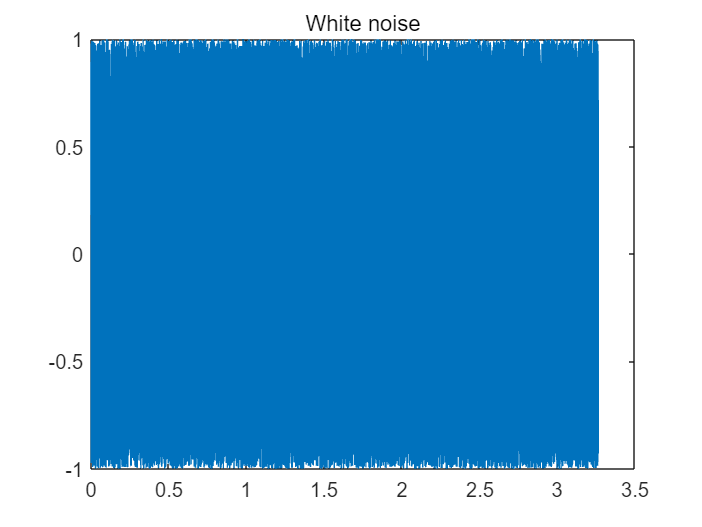

%generate white noise
noise = 1-2*rand(1,length(sig1));
plot(t,noise);title('White noise');

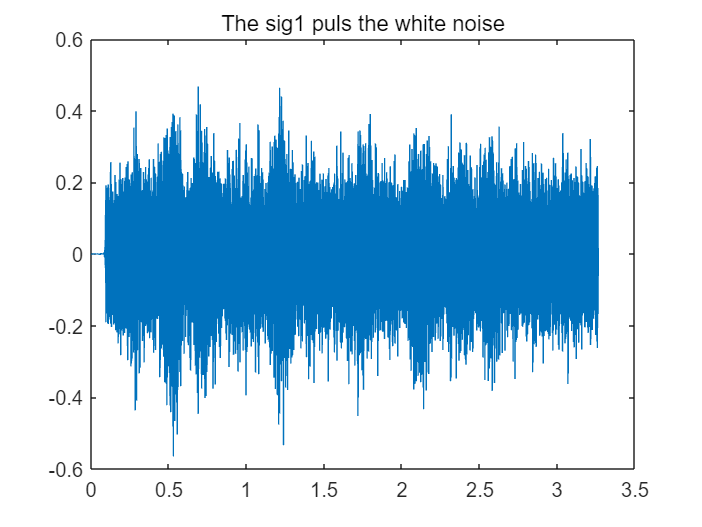

nfft=512; 
noverlap = nfft/2;
Windows = hamming(nfft);
[Pxx,w] = pwelch(sig1,Windows,noverlap,nfft,fs1);
b = fir2(3000,w/(fs1/2),sqrt(Pxx/max(Pxx)));
SSN = filter(b,1,noise);
%normalize the energy -5db
SSN = SSN/norm(SSN)*(10^0.25) *norm(sig1');
y1 = sig1' + SSN ;
figure
plot(t,y1),title('The sig1 puls the white noise')

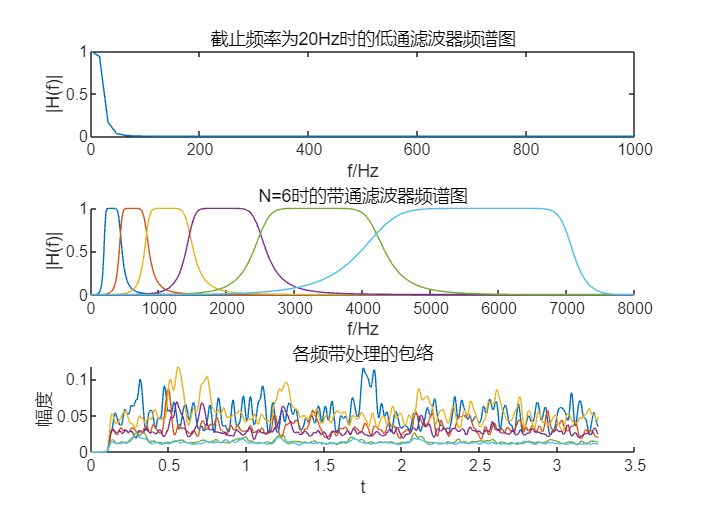


%Signal 1
sig1_6_20=tone_vocoder(y1',6,20,fs1);

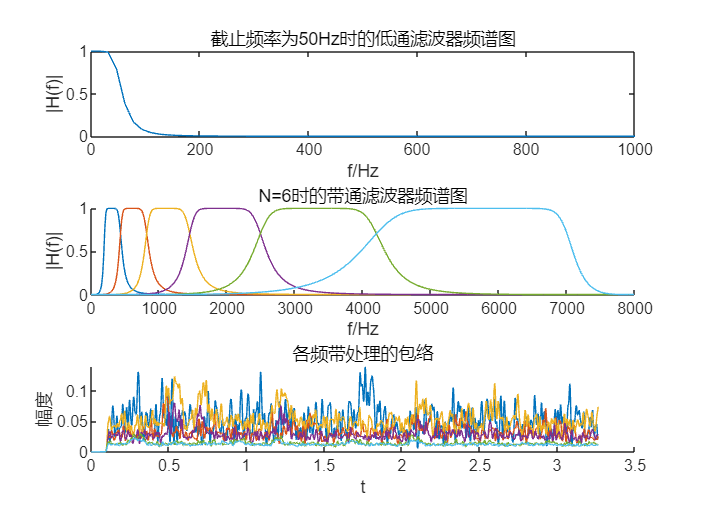

sig1_6_50=tone_vocoder(y1',6,50,fs1);

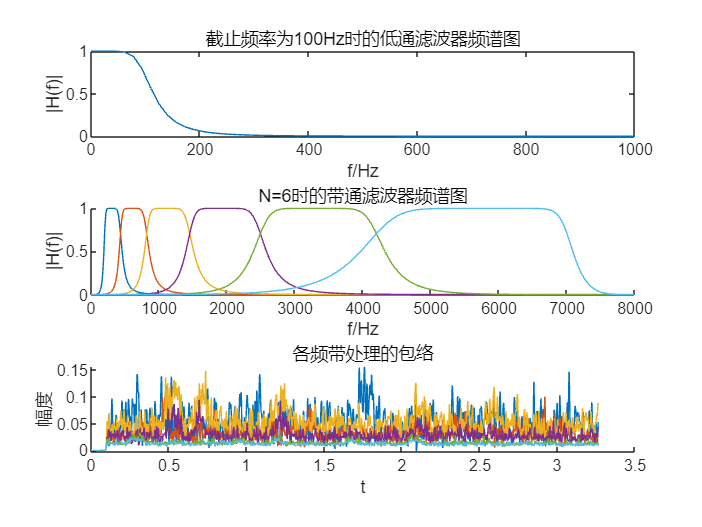

sig1_6_100=tone_vocoder(y1',6,100,fs1);

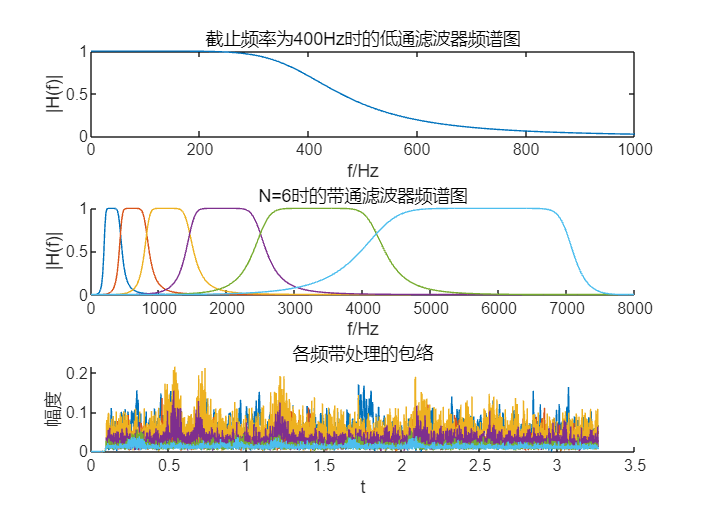

sig1_6_400=tone_vocoder(y1',6,400,fs1);

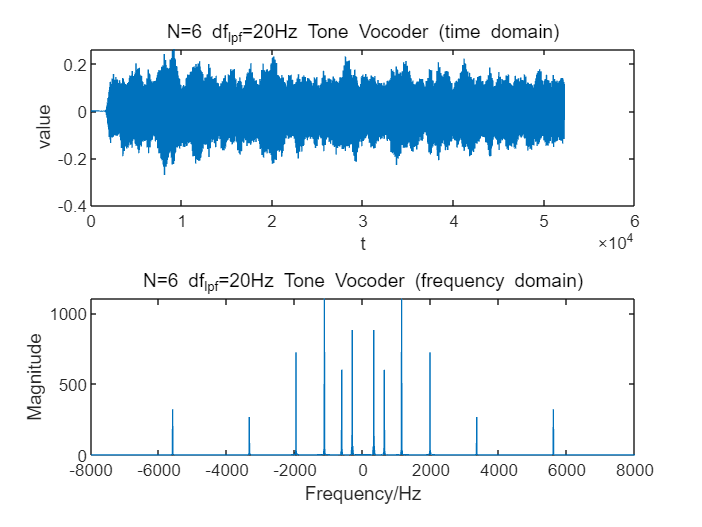

%获取合成信号的频谱
fftsig1_6_20=fftshift(fft(sig1_6_20));
fftsig1_6_50=fftshift(fft(sig1_6_50));
fftsig1_6_100=fftshift(fft(sig1_6_100));
fftsig1_6_400=fftshift(fft(sig1_6_400));

f1=linspace(-fs1/2,fs1/2,length(y1));
%绘制
figure(1)
subplot(2,1,1),plot(sig1_6_20),title('N=6 df_{lpf}=20Hz Tone Vocoder (time domain)'),
ylabel('value'),xlabel('t');
subplot(2,1,2),plot(f1,abs(fftsig1_6_20)),title('N=6 df_{lpf}=20Hz Tone Vocoder (frequency domain)'),
ylabel('Magnitude'),xlabel('Frequency/Hz');

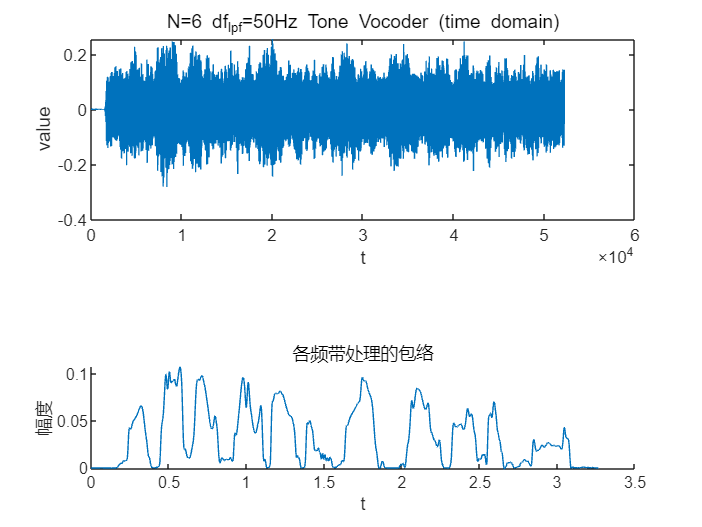


figure(2)
subplot(2,1,1),plot(sig1_6_50),title('N=6 df_{lpf}=50Hz Tone Vocoder (time domain)'),
ylabel('value'),xlabel('t');

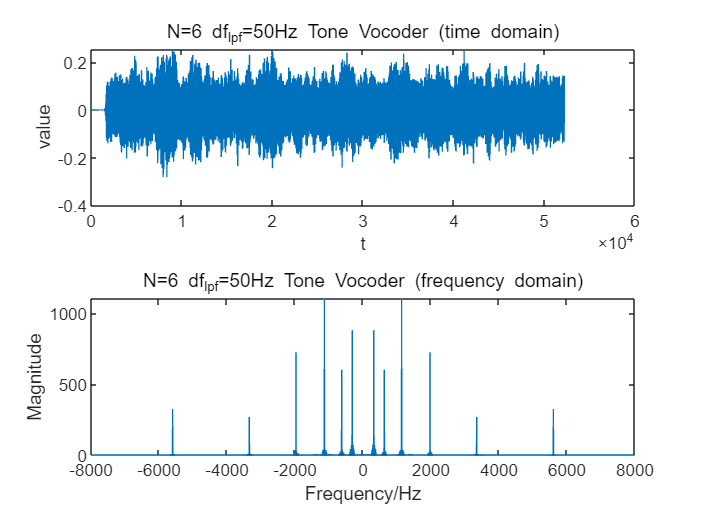

subplot(2,1,2),plot(f1,abs(fftsig1_6_50)),title('N=6 df_{lpf}=50Hz Tone Vocoder (frequency domain)'),
ylabel('Magnitude'),xlabel('Frequency/Hz');

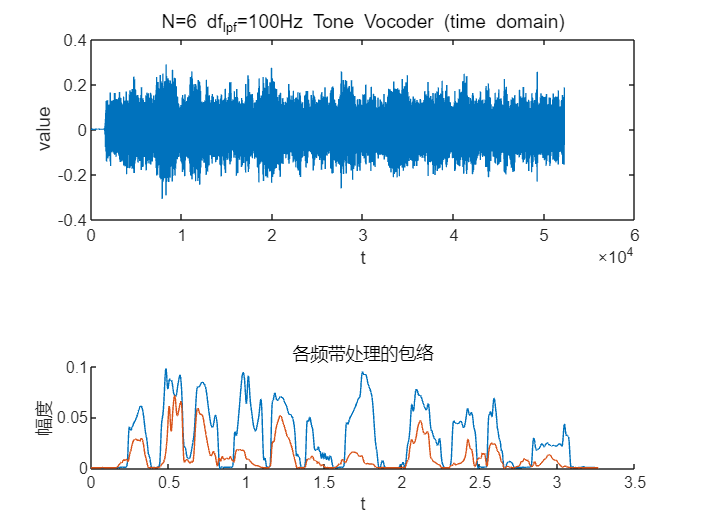

figure(3)
subplot(2,1,1),plot(sig1_6_100),title('N=6 df_{lpf}=100Hz Tone Vocoder (time domain)'),
ylabel('value'),xlabel('t');

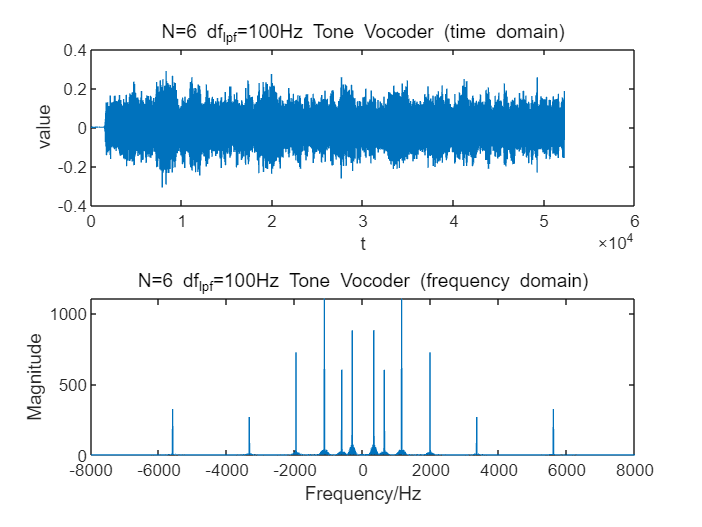

subplot(2,1,2),plot(f1,abs(fftsig1_6_100)),title('N=6 df_{lpf}=100Hz Tone Vocoder (frequency domain)'),
ylabel('Magnitude'),xlabel('Frequency/Hz');

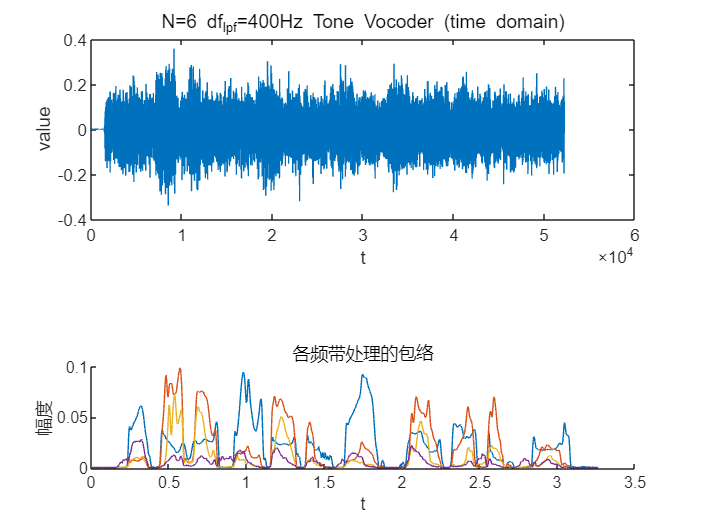

figure(4)
subplot(2,1,1),plot(sig1_6_400),title('N=6 df_{lpf}=400Hz Tone Vocoder (time domain)'),
ylabel('value'),xlabel('t');

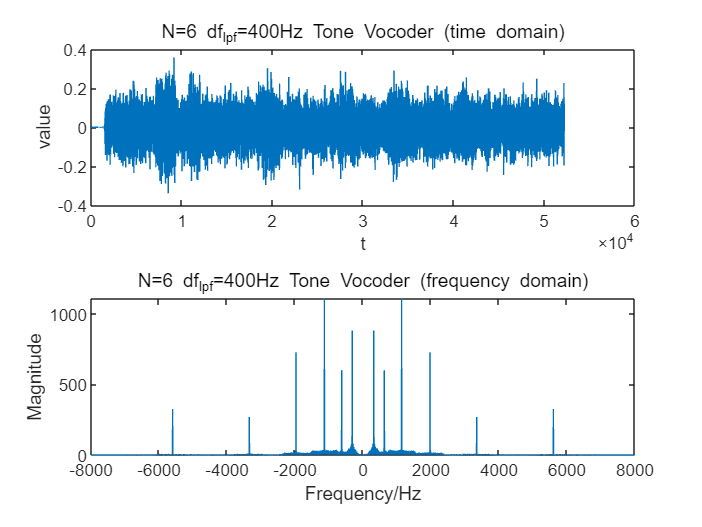

subplot(2,1,2),plot(f1,abs(fftsig1_6_400)),title('N=6 df_{lpf}=400Hz Tone Vocoder (frequency domain)'),
ylabel('Magnitude'),xlabel('Frequency/Hz');

%图像和音频信号的保存
%audiowrite("D:\MATLAB\project1 音频文件\Task4_sig1_6_20.wav",sig1_6_20,fs1)
%saveas(figure(1),'D:\MATLAB\project2 图像文件\Task4_sig1_6_20.jpg');
%audiowrite("D:\MATLAB\project1 音频文件\Task4_sig1_6_50.wav",sig1_6_50,fs1)
%saveas(figure(2),'D:\MATLAB\project2 图像文件\Task4_sig1_6_50.jpg');
%audiowrite("D:\MATLAB\project1 音频文件\Task4_sig1_6_100.wav",sig1_6_100,fs1);
%saveas(figure(3),'D:\MATLAB\project2 图像文件\Task4_sig1_6_100.jpg');
%audiowrite("D:\MATLAB\project1 音频文件\Task4_sig1_6_400.wav",sig1_6_400,fs1)
%saveas(figure(4),'D:\MATLAB\project2 图像文件\Task4_sig1_6_400.jpg');

%大拓展1:分析误差，并找到最佳方案
%一般均方误差分析
for i = 1:6
    for j = 1:4
        X(i,j) = Analysis(s,Nseq(i),fcutseq(j),fs);
    end
end
figure;
[x,y] = meshgrid([2,4,6,8,16,64],[20,50,100,400]);
surf(x',y',X);
title("均方误差");
xlabel("N");ylabel("fcut");zlabel("error");

%加权均方误差分析
figure
for i = 1:6
    for j = 1:4
        X(i,j) = optiAnalysis(s,Nseq(i),fcutseq(j));
    end
end
figure;
[x,y] = meshgrid([2,4,6,8,16,64],[20,50,100,400]);
surf(x',y',X);
title("加权均方误差");
xlabel("N");ylabel("fcut");zlabel("error");

%大拓展2：自己录制一段信号
% sigMine = recordSignal('mySig.wav', 2, 16000)
% sound(sigMine, 16000)
% 为方便测试，直接导入提前录好的音频；展示时，注释此行，恢复上面的录制部分
[sigMine, fs3] = audioread("mySig放假了.wav"); 

下面对录制的声音也进行同样的操作（可以通过修改sigTest, fsTest, NTest，方便地测试各个情况）：

sigTest = sigMine;
fsTest = fs3;
NTest = 64;
sigTest_NTest_50 = tone_vocoder(sigTest, NTest, 50, fsTest);
sound(sigTest_NTest_50, fsTest)
filename = "sigTest_NTest_50.wav";
audiowrite(filename, sigTest_NTest_50, fsTest);

function s = fseperator(N)
dlow=(log10(200/165.4+1))/0.06;
dhigh=(log10(7000/165.4+1))/0.06;
dsep=linspace(dlow,dhigh,N+1);
s=165.4.*(10.^(0.06.*dsep)-1);
end

%tone_vocoder函数，输入参数为音频信号x，通道数N，截止频率fcut，采样频率fs
function z = tone_vocoder(x,N,fcut,fs)
[b,a]=butter(4,fcut/(fs/2),"low");
[h,f] = freqz(b, a, 512, fs);
figure;
subplot(3,1,1), plot(f, abs(h)), 
title(strcat('截止频率为', num2str(fcut), 'Hz时的低通滤波器频谱图')), 
xlabel('f/Hz'), ylabel('|H(f)|'), xlim([0, 1000])

%使用fseperator函数在Bark频率范围内按照频率均匀地找到N+1个点
fd=fseperator(N);
% 向量转数组，长度N+1
fd=double(fd);
% 数组取整
fd=fix(fd); 

% 语音信号时长
t=0:1/fs:(length(x)-1)/fs; 
z=[zeros(1,length(x))]; 

%对每个频带进行处理
for i=1:N
    %设计一个带通滤波器，并对音频信号进行滤波和整流
    [B,A]=butter(4,[fd(i) fd(i+1)]/(fs/2));
    y=filter(B,A,x);
    [hband,f] = freqz(B,A,512,fs);
    subplot(3,1,2), hold on;
    plot(f,abs(hband))
    hold off;
    title(strcat('N=', num2str(N), '时的带通滤波器频谱图')), xlabel('f/Hz'), ylabel('|H(f)|')
    y=abs(y);

    %设计一个低通滤波器，并对滤波后的信号进行滤波，得到包络
    y=filter(b,a,y);
    subplot(3,1,3), hold on;
    plot(t, y)
    hold off;
    title(strcat('各频带处理的包络')), xlabel('t'), ylabel('幅度')
    
    %计算频带的中心频率，并生成一个相对应频率的正弦波
    ff=(fd(i)+fd(i+1))/2; 
    fsin=sin(2*pi*ff*t); 
    zN=(y').*fsin;

    %将包络和正弦波相乘，并生成一个对应的正弦波
    z=z+zN;
end
end




function error = optiAnalysis(sori,N,fcut)
fs = length(sori);
sgera = tone_vocoder(sori,N,fcut,fs);
Fs = length(sori);
L = length(sori);
Aori = fft(sori);
Agera = fft(sgera);
Var = 0;
P2_ori = abs(Aori/L);%计算双侧频谱
P2_gera = abs(Agera/L);
P1_ori = P2_ori(1:(L-1)/2);%计算单侧频谱
P1_gera = P2_gera(1:(L-1)/2);
P1_ori(2:end-1) = 2*P1_ori(2:end-1);
f = Fs*(0:(L-1)/2)/L;%当采样率和信号长度一致时，信号分辨率为1Hz
%根据等响度曲线，取感知声音在40phon的曲线在500Hz到1000Hz的响度为1，根据分贝的定义计算其余各频段的声音的能量比，将能量比作为相应的加权参数
for n = 1:length(P1_ori)
if f(n)<200
    factor = 0;
elseif f(n)>=200&f(n)<300
        factor = 0.208;
elseif f(n)>=300&f(n)<400
        factor = 0.4735;
elseif f(n)>=400&f(n)<500
        factor = 0.8155;
elseif f(n)>=500&f(n)<1000
        factor = 1;
elseif f(n)>=1000&f(n)<2000
        factor = 1.2925;
elseif f(n)>=2000&f(n)<3000
        factor = 2.783;
elseif f(n)>=3000&f(n)<4000
        factor = 3.981;
elseif f(n)>=4000&f(n)<5000
        factor = 2.988;
elseif f(n)>=5000&f(n)<6000
        factor = 1.156;
elseif f(n)>=6000&f(n)<7000
    factor = 0.208;
else 
    factor = 0;
end
Var = Var+(P1_ori(n)-P1_gera(n))^2*factor;
error = Var/length(sori);
end
end


function Var1 = Analysis(sori,N,fcut,fs)
sgera=tone_vocoder(sori,N,fcut,fs);
Var = 0;
for n = 1:length(sori)
    Var = Var + (sori(n)-sgera(n))^2;
end
Var1 = Var/length(sori);
end

function SSN = SSNgerator(s,fs)
N = length(s);
SNR = -5;
noise = 1-2*rand(1,N);%生成一个白噪声信号
[Pxx,w] = pwelch(s,hamming(512),256,512,fs);%得到语音信号幅度谱
b = fir2(3000,w/(fs/2),sqrt(Pxx/max(Pxx)));%得到语音信号的滤波系数
SSNori = filter(b,1,noise);%生成语音形状的噪声
normSSN =  norm(s)/(10^(SNR/20));
SSN = SSNori/norm(SSNori)*normSSN;%设置信噪比为-5dB
end

% 此函数用于将长度大于maxN的MATLAB信号矩阵从act开始截取maxN个数据，并取整，以供Keil使用。
function s = sigTrnsfrmer(sig, act, maxN) % maxN 为Keil中的N（不能过大，过大会报错）
if length(sig)>=maxN
    if iscolumn(sig)
        sig = sig';
    end
    s = round(32768.*sig(act:maxN+act-1));
end
end

% 根据提示录制一段音频，返回数据向量，并把音频用一个wave文件存储。录音结束后会有一遍回放
function sigRec = recordSignal(filename, time, fsRec, nBits, nChannels)
if(~exist('fsRec', 'var'))
    fsRec = 16000;
end

if(~exist('nBits', 'var'))
    nBits = 8;
end

if(~exist('nChannels', 'var'))
    nChannels = 1;
end

recorder = audiorecorder(fsRec, nBits, nChannels);
disp('录音开始')
recordblocking(recorder, time);
disp('录音结束')
% 录音回放
play(recorder)
sigRec = getaudiodata(recorder);
audiowrite(filename, sigRec, fsRec)
end